filepath= "images\starfish_noise4.jpg";

disp(filepath)

images\starfish_noise4.jpg


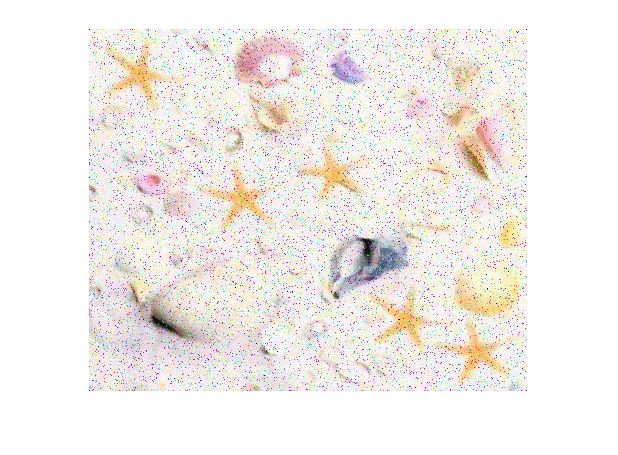


im = imread(filepath);
imshow(im);

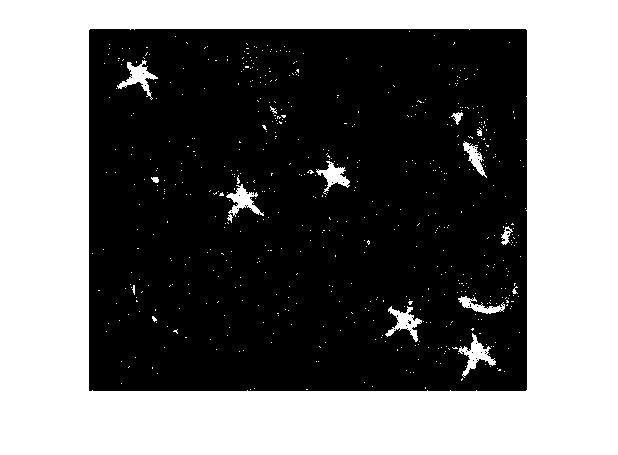


mask = double(ThresholdRGB(im));
imshow(mask);


im = imbinarize(mask, 0.2);
imshow(mask);

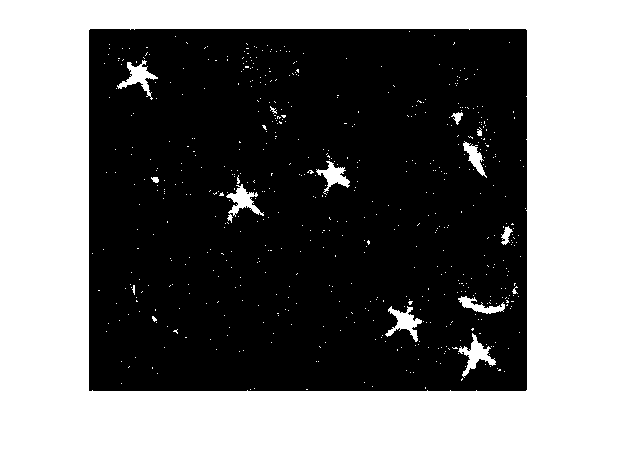


im = imfill(im, 'holes');
imshow(im);

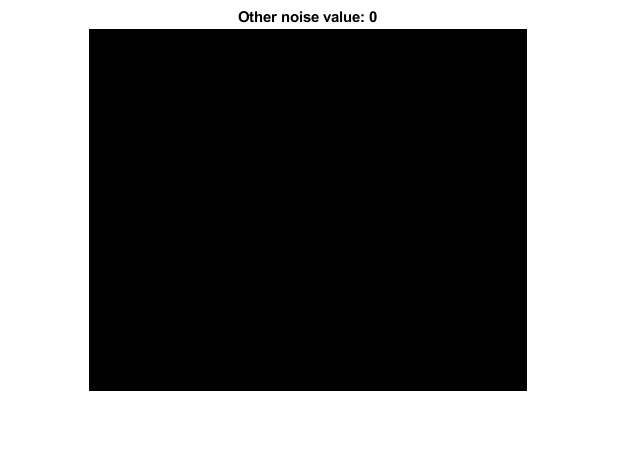

Method used: medianfilter




im = DenoiseIsolated(im, 'medianfilter');

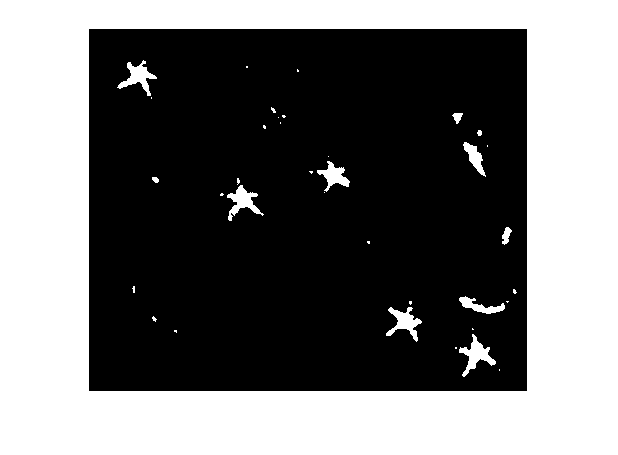

im = imfilter(im, ones(3)/9, 'same');
imshow(im);


[c1,c2,c3] = imsplit(im);

Error using imsplit (line 57)
Too many output arguments.

im = c2;
imshow(im);

im = DenoiseIsolated(im, 'medianfilter');
im = imfilter(im, ones(3)/9, 'same');
imshow(im);

% Increase contrast.
% im = imadjust(im);
% imshow(im);
% im = im*2;
% imshow(im);

level = graythresh(im);
imshow(im);
im = imbinarize(im, level);
% im = im;
imshow(im);

% Helps with the noiser images.
se = strel('disk', 2);
im = imclose(im, se);

% General morph ops.
se = strel('line', 1, 45);
im = imopen(im, se);
se = strel('line', 1, 90);
im = imopen(im, se);
se = strel('line', 1, 135);
im = imopen(im, se);
se = strel('line', 1, 180);
im = imopen(im, se);

im = bwareafilt(im, [400 1000000]);

% cc = bwconncomp(im);
 
% 
% chull = bwconvhull(im);
% imshow(cc);

% MSER
regions = detectMSERFeatures(im);
figure;
imshow(im);
hold on;
plot(regions,'showPixelList',true,'showEllipses',false);

function diffMask = GetDiffMask(im, imP)
% Get mask of "isolated" noise.
imLnStd = log(std2(im))^2;
diff = abs(double(im) - double(imP));
diffMask = (diff > imLnStd);
end
% % % %


function noisePercent = GetRelPercentageNoise(im, noiseMask)
noisyPixels = sum(noiseMask(:));
nPx = numel(im);
noisePercent = (100/nPx) * noisyPixels;
end
% % % %


function [imP, noiseValue] = DenoiseIsolated(im, method)
maxPasses = 10;
changeThresh = 50;
dims = ndims(im);
repeat = true;
attempt = 0;


while (repeat && attempt < 3)
    attempt = attempt + 1; % try median and then try mean
    noiseValue = 100; % Reset
    passes = 0; % Reset
    repeat = false;
    imP = im;

    if (dims == 2)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated2D(imP, method);
            passes = passes + 1;
        end
    elseif (dims == 3)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated3D(imP, method);
            passes = passes + 1;
        end
    else
        error("Unsupported number of dimensions. Expected a 2D or 3D array.");
    end
    
    % Outputs in the range of 20-40 are resultant of noisy images benfitting from non-median filter techniques.
%     if (noiseValue > 30)
%         disp("Switching mode");
%         method = "meanfilter";
%         repeat = true;
%     end
    % else finish.
end

disp("Method used: " + method);

%     imP = imsharpen(imP, 'amount', 2);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated3D(im, method)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noiseValue1] = DenoiseIsolated2D(ch1, method);
[dnCh2,noiseValue2] = DenoiseIsolated2D(ch2, method);
[dnCh3,noiseValue3] = DenoiseIsolated2D(ch3, method);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noiseValue = mean([noiseValue1,noiseValue2,noiseValue3]);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated2D(im, method)
% if s&p or isolated noise
if (method == "medianfilter")
    filtered = medfilt2(im, [5 5]); % [5 5] loses texture but keeps shape. [3 3] keeps texture but more noise.
elseif (method == "meanfilter")
    filtered = conv2(im, ones(3)/9, 'same');
end

diffMask = GetDiffMask(im, filtered);

% Swap noisy pixels for filtered ones
noise = (diffMask == 1);
imP = im;
imP(noise) = filtered(noise);

diffMask = GetDiffMask(im, imP);
noiseValue = GetRelPercentageNoise(im, diffMask);
imshow(diffMask)
title("Other noise value: " + round(noiseValue,2))
end
% % % %

function [BW,maskedRGBImage] = ThresholdRGB(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 09-May-2020
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.847;
channel1Max = 0.157;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.400;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
